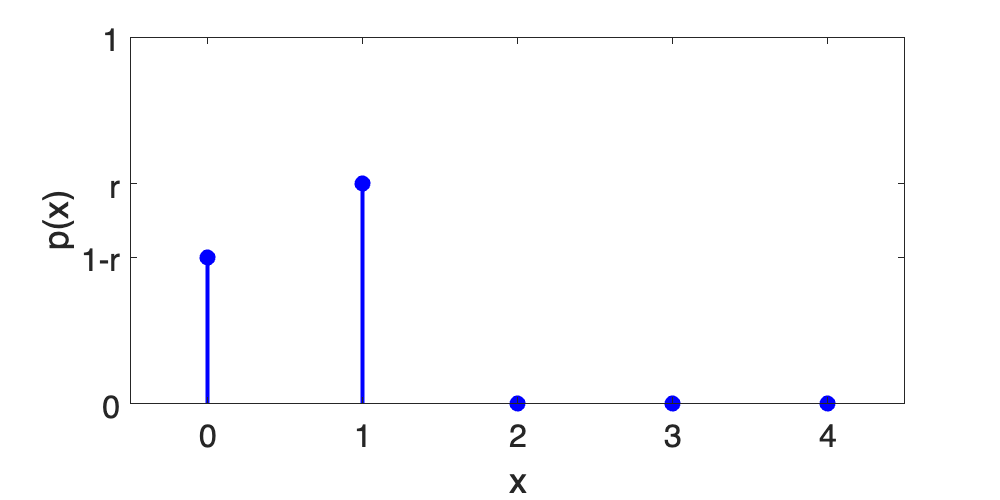

% bernoulli pmf
r=0.6;
X = [0 1 2 3 4];
Y = [1-r r 0 0 0];
stem(X, Y, "filled", 'LineWidth', 2, "Color", "blue");

xlim([X(1)-0.5 X(end)+.5]);
xticks(X);
xlabel("x");

ylim([0 1]);
yticks([0 1-r r 1]);
yticklabels(["0", "1-r" "r", "1"]);
ylabel("p(x)");

ax = gca;
ax.FontSize = 16; 

set(gcf,'position', [0, 0, 600, 300]);

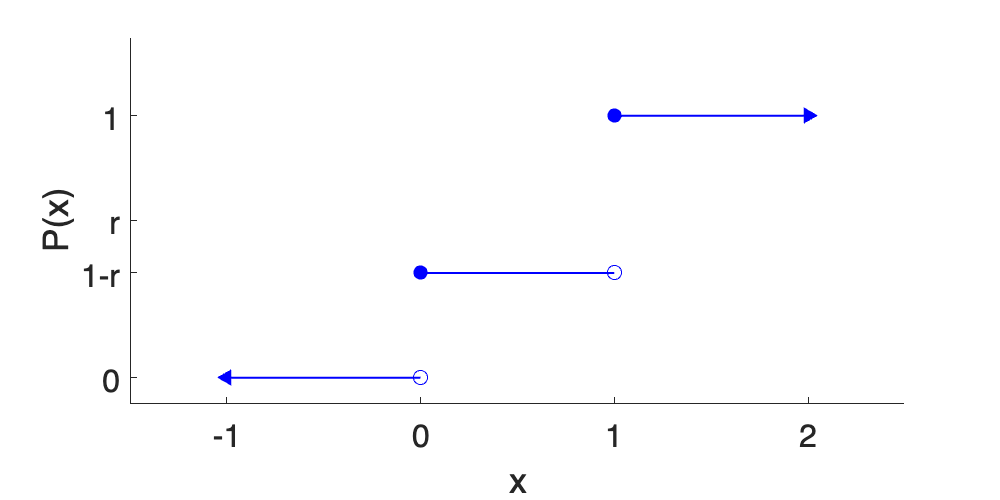

% bernoulli cdf
x = [-1 0 1 2];
y = cumsum([0 1-r r 0]);

stairs2(x, y);
xlim([x(1)-0.5 x(end)+.5]);
xticks(x);
xlabel("x");

ylim([-0.1 1.3]);
yticks([0 1-r r 1]);
yticklabels(["0", "1-r" "r", "1"]);
ylabel("P(x)");

ax = gca;
ax.FontSize = 16; 

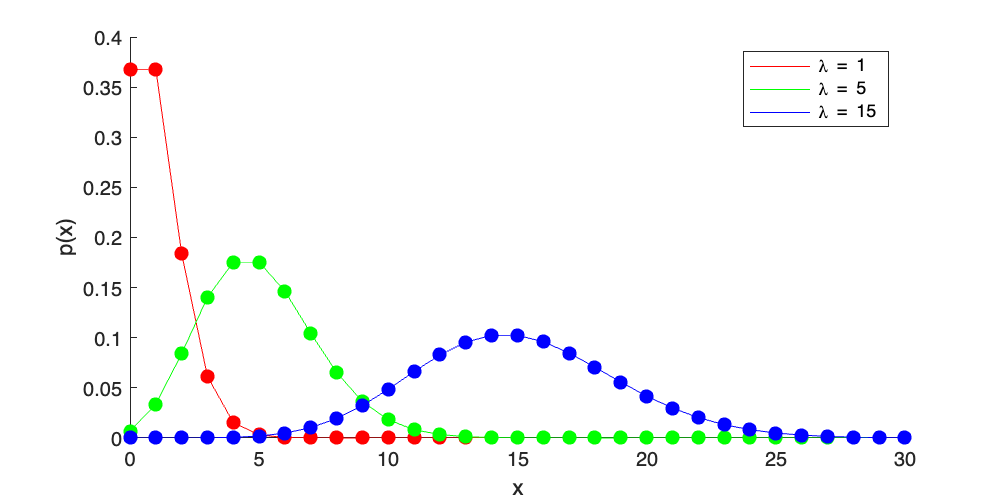


set(gcf,'position',[0, 0, 600, 300]);

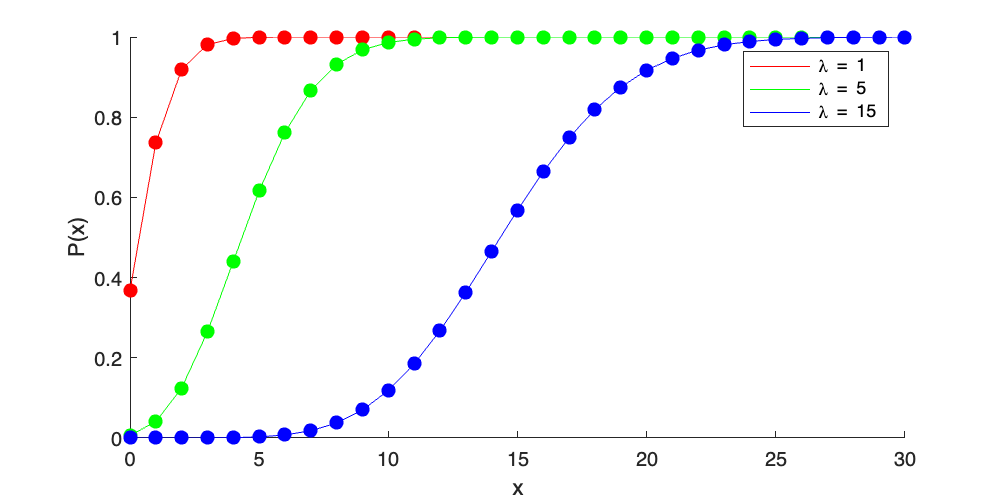

ans =    -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


ans =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


xc =     0.3954    2.5162   -3.3541    7.1272   -8.0006    1.6813   -0.7500   -6.0940   -1.9182    8.4412    1.8816   -3.5458    6.1224   -1.4804   -7.4599    0.2510   -9.6961    2.6004   -2.6491   -1.9341   -8.4805    6.1524   -3.1153   -4.9565   -2.3293    6.1062   -5.1339   -2.7021    1.2730    0.1569    1.7473    6.0096   -0.3593    0.2549   -9.0821    1.0263    7.5837    7.2489   -4.3245    9.0316   -8.1176   -5.7994   -5.5740    5.2096    2.1204    4.1227   -9.8975    4.7905    2.0717   -5.2938


% poisson pmf / cdf
x = 0:30;
lambdas = [1 5 15];
colors = ["red", "green", "blue"];
Legend = cell(length(lambdas), 1);

clf('reset');
hold on;
for il=1:length(lambdas)
    l = lambdas(il);
    c = colors(il);
    y = poisscdf(x, l);  % pdf/cmf
    plot(x, y, "Color", c);
    scatter(x, y, 50, c, "filled");
    Legend{(il-1) * 2 + 1} = "\lambda = " + l;
    Legend{(il-1) * 2 + 2} = '';
end
legend(Legend);

xlabel("x");
ylabel("P(x)");  % p/P
hold off;

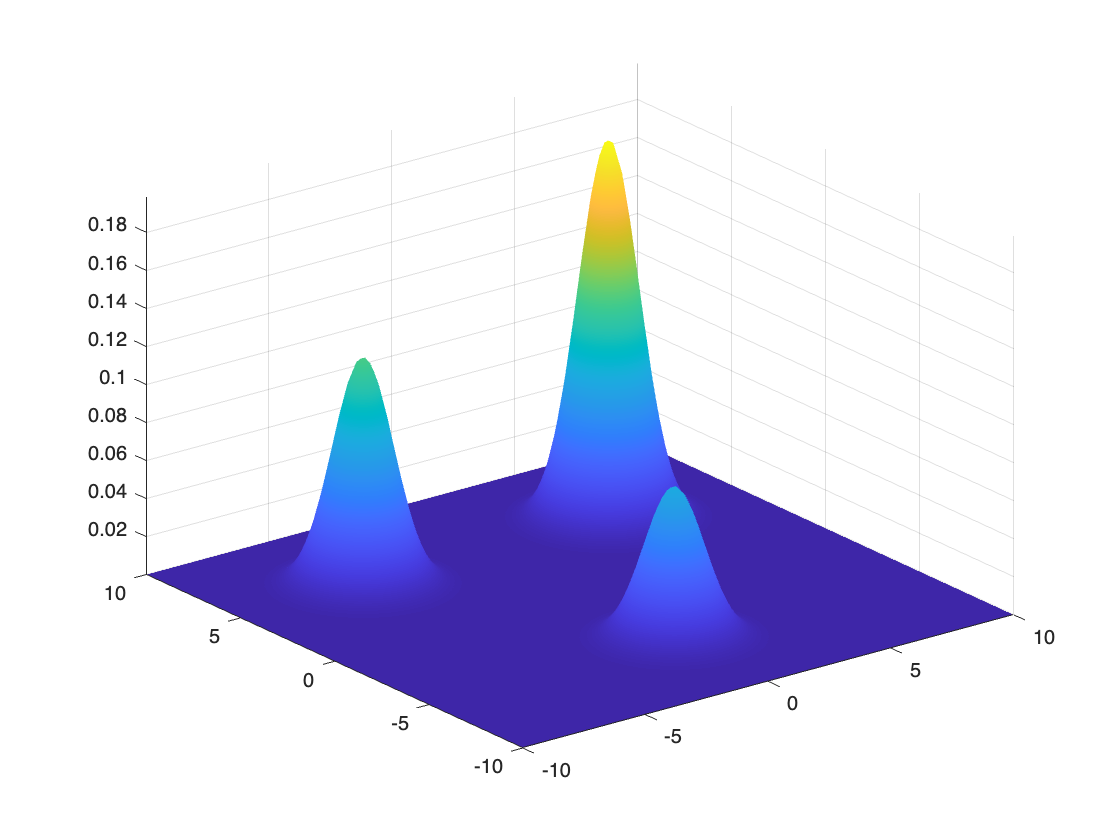

ans =      1     2


X1 =   -10.0000   -9.9394   -9.8788   -9.8182   -9.7576   -9.6970   -9.6364   -9.5758   -9.5152   -9.4545   -9.3939   -9.3333   -9.2727   -9.2121   -9.1515   -9.0909   -9.0303   -8.9697   -8.9091   -8.8485   -8.7879   -8.7273   -8.6667   -8.6061   -8.5455   -8.4848   -8.4242   -8.3636   -8.3030   -8.2424   -8.1818   -8.1212   -8.0606   -8.0000   -7.9394   -7.8788   -7.8182   -7.7576   -7.6970   -7.6364   -7.5758   -7.5152   -7.4545   -7.3939   -7.3333   -7.2727   -7.2121   -7.1515   -7.0909   -7.0303
  -10.0000   -9.9394   -9.8788   -9.8182   -9.7576   -9.6970   -9.6364   -9.5758   -9.5152   -9.4545   -9.3939   -9.3333   -9.2727   -9.2121   -9.1515   -9.0909   -9.0303   -8.9697   -8.9091   -8.8485   -8.7879   -8.7273   -8.6667   -8.6061   -8.5455   -8.4848   -8.4242   -8.3636   -8.3030   -8.2424   -8.1818   -8.1212   -8.0606   -8.0000   -7.9394   -7.8788   -7.8182   -7.7576   -7.6970   -7.6364   -7.5758   -7.5152   -7.4545   -7.3939   -7.3333   -7.2727   -7.2121   -7.1515   -7.0909   -

% gaussian mixture
clf('reset');
gauss = @(X, Y) ...
    0.2 * (1/sqrt(2*pi).*exp(-(X.^2/2)-((Y + 5).^2/2))) + ...
    0.3 * (1/sqrt(2*pi).*exp(-((X + 5).^2/2)-((Y - 5).^2/2))) + ...
    0.5 * (1/sqrt(2*pi).*exp(-((X - 5).^2/2)-((Y - 5).^2/2)));

x1 = linspace(-10., 10.);
y1 = x1;
[X1,Y1] = meshgrid(x1,y1);
z1=gauss(X1, Y1);
surf(X1,Y1,z1);
shading interp
axis tight

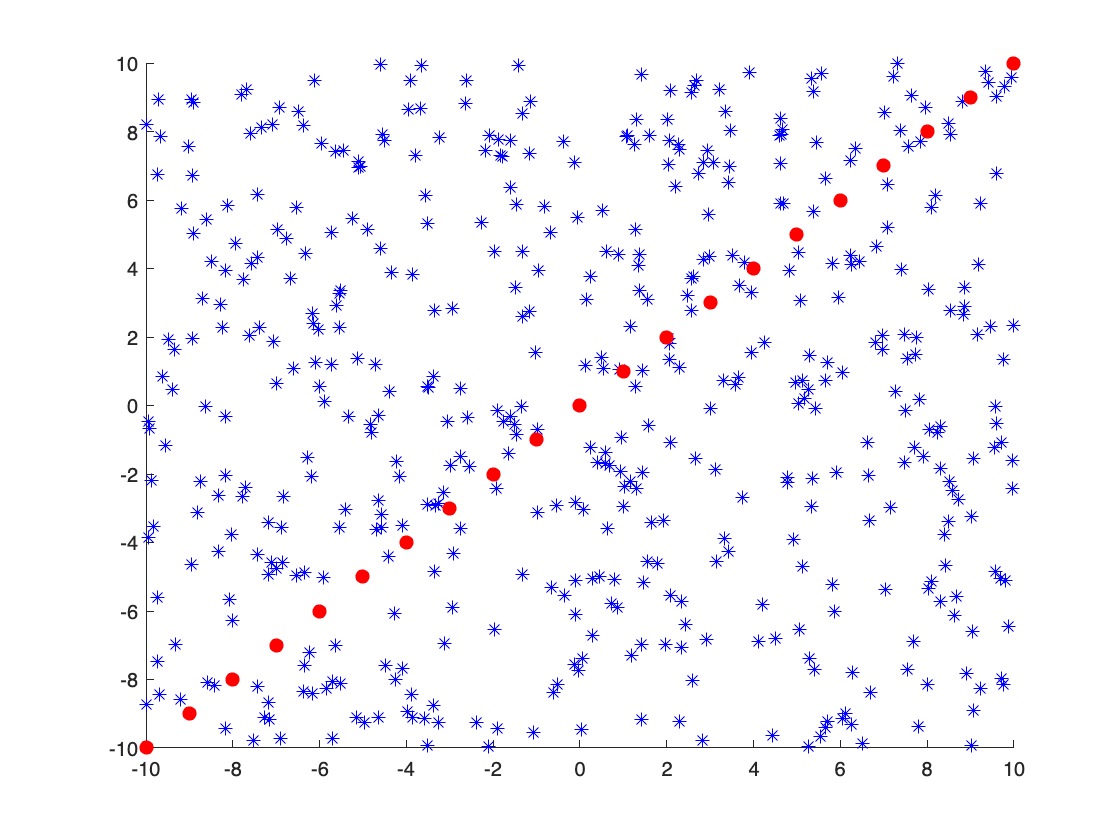

% clutter intro
xc = rand(1, 500) * 20 - 10;
yc = rand(1, 500) * 20 - 10;
x = -10:10;
y = -10:10;
clf('reset');
hold on;
scatter(xc, yc, 50, "blue", "*");
scatter(x, y, 50, "red", "filled", "o");
hold off;

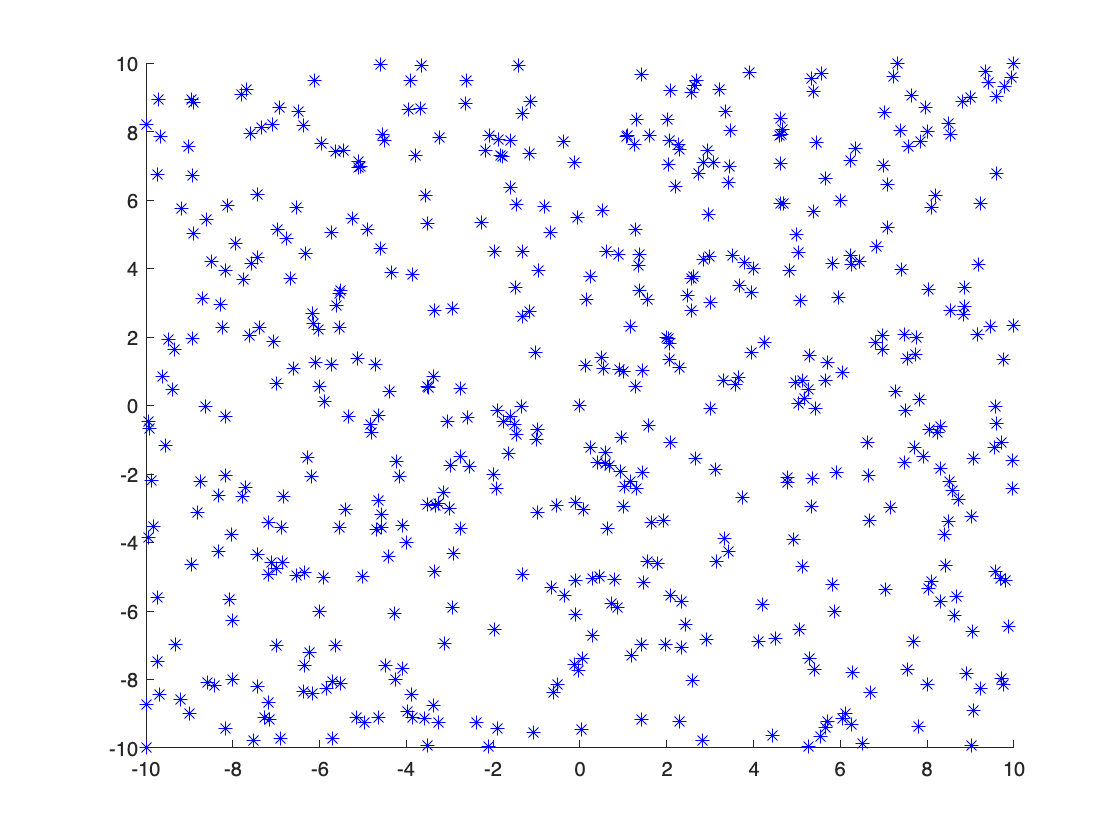


clf('reset');
hold on;
scatter(xc, yc, 50, "blue", "*");
scatter(x, y, 50, "blue", "*");
hold off;

% phd function example
clf('reset');

means = {
    [-25 10].'
    [-46 10].'

    [5 10].'
    [0 10].'

    [50 10].'
    [40 10].'
};

covs = {
    diag([10 1]).^2
    diag([10 1.3]).^2

    diag([10 2]).^2
    diag([10 2]).^2

    diag([15 2]).^2
    diag([15 2]).^2
};

weights = {
    0.6
    0.4

    0.8
    0.6

    0.85
    0.65
};

x1 = linspace(-100., 130.);
y1 = linspace(-20., 30.);
[X1,Y1] = meshgrid(x1,y1);
[z, integral] = gauss_mixture(X1, Y1, means, covs, weights, 0.0001);
% z = z * length(means);

z = z ./ 2;
sum(z, "all")

ans = 3.6803

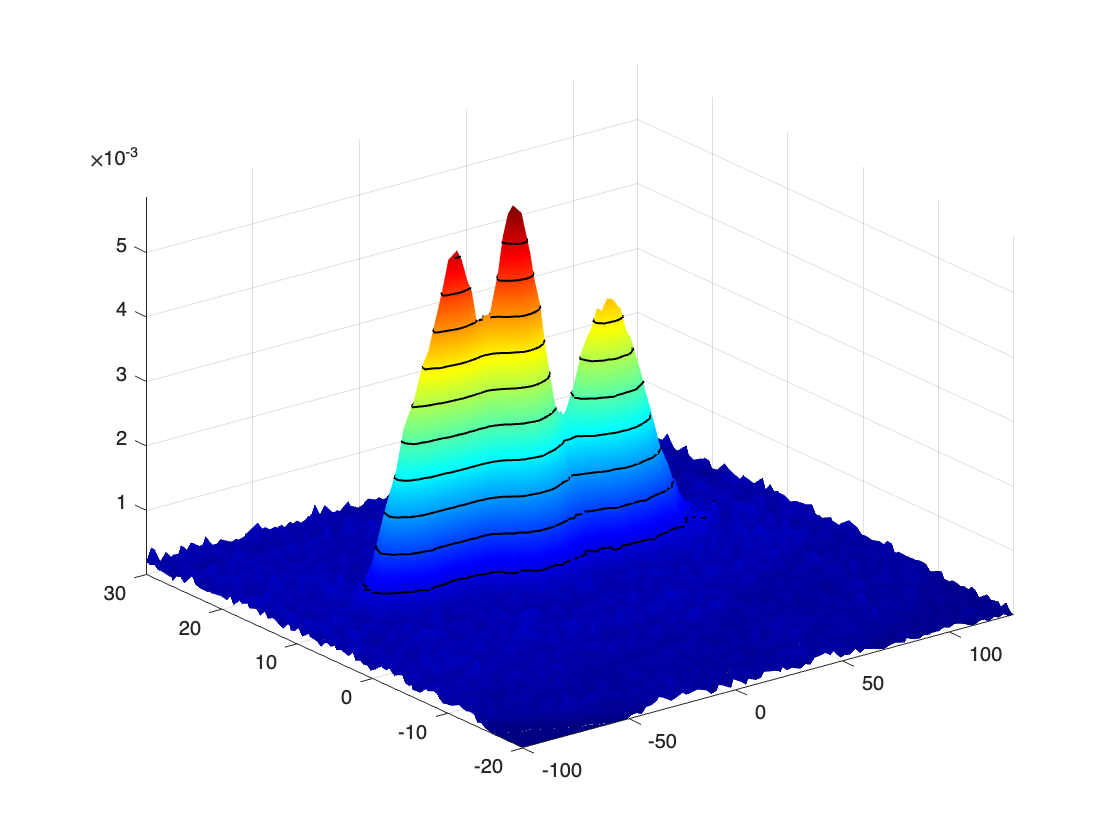


surf(X1,Y1,z, 'EdgeColor','none');
hold on;
contour3(X1,Y1,z, 10, '-k', 'LineWidth', 1.0)
hold off;
grid on
colormap('jet')
shading interp
axis tight

function [res, integral] = gauss_mixture(Xmesh, Ymesh, means, covs, weights, noise_var)
    res = zeros(size(Xmesh, 1), size(Xmesh, 2));
    integral = 0.;
    for compidx=1:length(means)
        mean = means{compidx};
        cov = covs{compidx};
        w = weights{compidx};

        for xi=1:size(Xmesh, 1)
            for yi=1:size(Xmesh, 2)
                x = Xmesh(xi, yi);
                y = Ymesh(xi, yi);
                v = [x y].';
                z = 1 / (2 * pi * sqrt(det(cov))) * exp((-1/2) * ((v - mean).' / cov * (v - mean)));
                z = z * w;
                if z < 0
                    error("FALSE");
                end
                % integral = integral + z;
                nearZero = @(x,tol) abs(x) < tol;
                if ~nearZero(z, 1e-57)
                    z = z + log(1 + abs(normrnd(0, noise_var)));
                end
                res(xi, yi) = res(xi, yi) + z;
            end
        end
    end
    integral = sum(res, "all");
end

function wnoise = noise_mesh(m, noise_var)
    n = normrnd(0, noise_var, [size(m, 1), size(m, 2)]);
    wnoise = m + n;
end

function stairs2(x,y)
    clf('reset');
    hold on;
    for i=1:length(x)-1
        if i ~= 1
            scatter(x(i), y(i), 50, 'blue', 'filled', 'o');
        else
            scatter(x(i), y(i), 50, 'blue', 'filled', '<');
        end
        plot(x(i:i+1),[y(i) y(i)], 'Color', "blue", "LineWidth", 1);
        if i ~= length(x)-1
            scatter(x(i+1), y(i), 50, 'blue', 'o');
        else
            scatter(x(i+1), y(i), 50, 'blue', 'filled', '>');
        end
    end
    hold off;
end